clear all ; 

n = 1000 ; % number of cells in the simulation

num_N = 60 ; % total number of different N (number of molecules per cell) 

%5:5:100 ; % number of molecules per cell

delta_N_half = zeros(n,num_N)  ; %matrix to store difference between the number of molecules in two doughter cells

N = 1 ; % starting total number of molecules to do simulation with

N_vec = []  ;

for i = 1:num_N % repeat simulation at different values of molecules per cell

    for j = 1:n % simulate individual cells

        n1 = binornd( N , 0.5 ) ;  % drow number of molecules in one of the doughter cells 

        delta_N_half(j,i) = ( n1 - N/2 )  ; % difference between two doughter cells

    end

    N = N + 2 ;  % increment the number of molecules per cell  

    N_vec = [ N_vec N ]  ;   % store number of molecules in a vector 

end

delta_N_half_sq_mean = sqrt( mean( delta_N_half.^2 ) )  ;  %  calculate root mean square (RMS) half molecule difference

% plot( N_vec , delta_N_half_sq_mean )  ; % plot simulated dependance
% 
% ylim([0,6])
% 
% hold on ;

ft = fittype('a*sqrt(x)') ;  % Define the type of fit (sqaure rooth with one free parameter).

[fittedModel, gof] = fit( N_vec', delta_N_half_sq_mean' , ft ) ; % do the fit


% Display the fitted coefficients
coeffvals = coeffvalues(fittedModel);
a = coeffvals(1); % fit coeffcient
fprintf('Fitted coefficient: a = %f', a ) ; %note that this should be close to 1/2 as per theory calculations 

Fitted coefficient: a = 0.493326

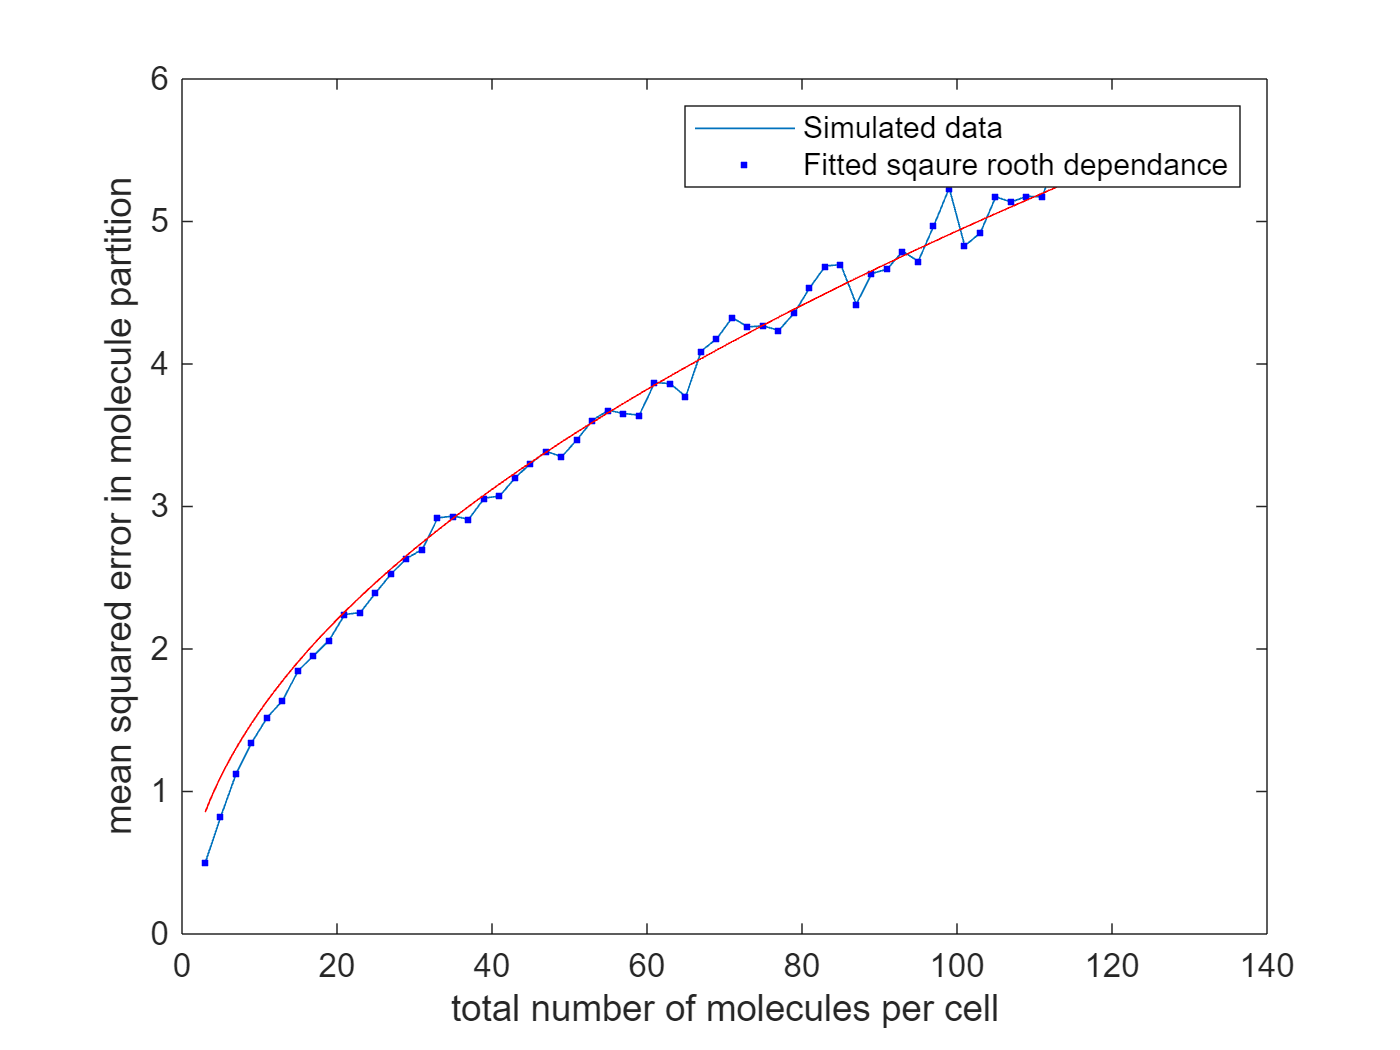


% Plot the original data and the fitted curve for visualization
plot(fittedModel, N_vec , delta_N_half_sq_mean );
xlabel('total number of molecules per cell');
ylabel('mean squared error in molecule partitioning');
legend('Simulated data', 'Fitted sqaure rooth dependance');


hold off